## **National Institute for Astrophysics, Optics, and Electronics**

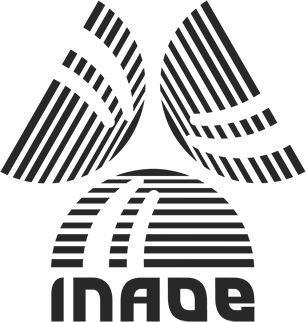

### **MSc. Science & Technology of Space**

# **ROS bag file to PNG conversion**

**Jorge Alberto Prado Herrada**

                                           ***                   Spring 2023***

`We need to obtain certain information from the ROS .bag file in order to extract the messages and convert them to image, in this live script we will be saving images in .PNG format. `

`The input for this next command will be your .bag File Name, assuming you're already on the folder where your file is, otherwise uncomment the first line and paste the path where your files are. `


%cd("D:\User\YourFolderPath\")


***rosbag info:*** helps the visualization of the information in the rosbag log file

rosbag info 's3li_mapping.bag'

Path:     D:\Jorge Prado\HiDive_Bagfiles\s3li_mapping.bag
Version:  2.0
Duration: 7:31s (451s)
Start:    Jul 08 2021 07:07:54.29 (1625746074.29)
End:      Jul 08 2021 07:15:25.90 (1625746525.90)
Size:     9.0 GB
Messages: 818342
Types:    geometry_msgs/QuaternionStamped [e57f1e547e0e1fd13504588ffc8334e2]
          geometry_msgs/Vector3Stamped    [7b324c7325e683bf02a9b14b01090ec7]
          sensor_msgs/CameraInfo          [c9a58c1b0b154e0e6da7578cb991d214]
          sensor_msgs/Image               [060021388200f6f0f447d0fcd9c64743]
          sensor_msgs/Imu                 [6a62c6daae103f4ff57a132d6f95cec2]
          sensor_msgs/PointCloud2         [1158d486dd51d683ce2f1be655c3c181]
          sensor_msgs/TimeReference       [fded64a0265108ba86c3d38fb11c0c16]
Topics:   /bf_lidar/points_raw         2120 msgs  : sensor_msgs/PointCloud2        
          /imu/data                  180638 msgs  : sensor_msgs/Imu                
          /imu/dq                    180637 msgs  : geometry_msg

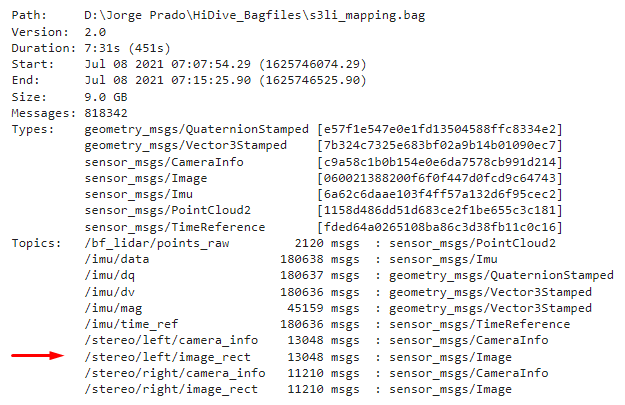

In this case, the images we're going to extract are in the topic "/stereo/left/image_rect", we will use this topic in the next lines of code

***bag = rosbag (rosbag.bag) ***creates an indexable BagSelection object

bag  = rosbag('s3li_mapping.bag');

***bagSel = select(bag, "Topic", "/stereo/left/image_rect"): ***Selects a specific topic, in this case it is the left camera images topic, which we obtained earlier. 

bagSel = select(bag, "Topic", "/stereo/left/image_rect")

bagSel =   BagSelection with properties:

           FilePath: 'D:\Jorge Prado\HiDive_Bagfiles\s3li_mapping.bag'
          StartTime: 1.6257e+09
            EndTime: 1.6257e+09
        NumMessages: 13048
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [13048×4 table]



% bagSelr = select(bag, "Topic", "/stereo/right/image_rect")

***msgStructs = readMessages(bagSel, 'DataFormat','struct'): ***Calls a function to read the messages in the bagSel variable 

msgStructs = readMessages(bagSel, 'DataFormat','struct');

images_folder = cd("\mapping_left\") %change your desired output folder here

current_folder = 'D:\Jorge Prado\HiDive_Bagfiles'


for i = 1:length(msgStructs)

    msg = copyImage(msgStructs{i});
    I = readImage(msg);
    rgbImage = cat(3, I, I, I);

    file_name = sprintf('Image_left%d.png',i); %change your desired file name here
    imgName = fullfile(images_folder,file_name);
    imwrite(rgbImage, imgName);
    imshow(imread(rgbImage))
end

function msg = copyImage(msgStruct)
    msg = rosmessage(msgStruct.MessageType);
    fNames = fieldnames(msg);
    for k = 1:numel(fNames)
        if ~any(strcmp(fNames{k}, {'MessageType', 'Header'}))
            msg.(fNames{k}) = msgStruct.(fNames{k});
        end
    end
end

#### Bibliography

Giubilato, R., Sturzl, W., Wedler, A., & Triebel, R. (2022). Challenges of SLAM in Extremely Unstructured Environments: The DLR Planetary Stereo, Solid-State LiDAR, Inertial Dataset. *IEEE Robotics and Automation Letters*, *7*(4), 8721–8728. [https://doi.org/10.1109/LRA.2022.3188118](https://doi.org/10.1109/LRA.2022.3188118)

*How do I get readImage (ROS) to work?* (n.d.). Retrieved February 14, 2023, from [https://la.mathworks.com/matlabcentral/answers/455547-how-do-i-get-readimage-ros-to-work](https://la.mathworks.com/matlabcentral/answers/455547-how-do-i-get-readimage-ros-to-work)

*Open and parse rosbag log file—MATLAB rosbag—MathWorks América Latina*. (n.d.). Retrieved February 14, 2023, from [https://la.mathworks.com/help/ros/ref/rosbag.html#d124e12755](https://la.mathworks.com/help/ros/ref/rosbag.html#d124e12755)